# 2.5. Determinación del espacio de trabajo

Los pasos a seguir para determinar el espacio de trabajo de un robot son los siguientes:

- Definición del robot y sus limites articulares (`min_lim, max_lim)`

- Generación de diferentes combinaciones de configuraciones articulares del robot.

Cálculo de todas las combinaciones posibles :

Cálculo de algunas posibles combinaciones (recomendado cuando el robot cuenta con múltiples gdls)[1]:

        3. Cálculo de la cinemática directa

- Opcion 1: Mediante las tres ecuaciones cinemáticas: `X = f(qi); Y=f(qi); Z=f (qi)`

- Opción 2: Mediante la multiplicacion de las matrices de transformación homogéneas: `AT = A1*A2*...An`

- Opción 3: Mediante la función` getTransform()`

        4. Graficar la nube de puntos con la función `plot3`

Biografía de interés:

*Yazdanpanah A., R. "Development of Direct Kinematics and Workspace Representation for Smokie Robot Manipulator & the Barret WAM" in 5th International Conference on Robotics and Mechatronics (ICROM),Tehran, Iran, 2017*

## Espacio de trabajo de un robot planar de 2 gdl

Definimos los parámetros geométricos del robot

clear
close all
a1 = 0.3; a2 = 0.2;
theta1_min = 0; theta1_max = pi/2;
theta1= pi/8; theta2_min = 0;
theta2_max = pi; theta2 = pi/4;
dhparams = [a1 0 0 theta1;
            a2 0 0 theta2];

Creación del rigidbodytree

robot = rigidBodyTree ('DataFormat', 'column');

body1 = rigidBody('body1'); jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'dh'); jnt1.HomePosition = theta1;
jnt1.PositionLimits = [theta1_min, theta1_max];
body1.Joint = jnt1; addBody(robot,body1,'base')

body2 = rigidBody('body2'); jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,dhparams(2,:),'dh'); jnt2.HomePosition = theta2;
jnt2.PositionLimits = [theta2_min, theta2_max];
body2.Joint = jnt2; addBody(robot,body2,'body1')
showdetails(robot)

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   
--------------------


Definición del espacio de trabajo del robot

step = 0.1;
vTheta1 = theta1_min:step:theta1_max; % all possible theta1 values
vTheta2 = theta2_min:step:theta2_max; % all possible theta2 values

% npuntos = 15;
% vTheta1 = linspace(theta1_min, theta1_max, npuntos); 
% vTheta2 = linspace(theta2_min, theta2_max, npuntos); 


[THETA1,THETA2] = meshgrid(vTheta1,vTheta2); % generate grid of angle values
%Cálculo X,Y utilizando la opción 1 (mediante las ecuaciones de cinemática)
X = a1 * cos(THETA1) + a2 * cos(THETA1 + THETA2); % compute x coordinates
Y = a1 * sin(THETA1) + a2 * sin(THETA1 + THETA2); % compute y coordinates

Visualización de la trayectoria y del espacio de trabajo del robot

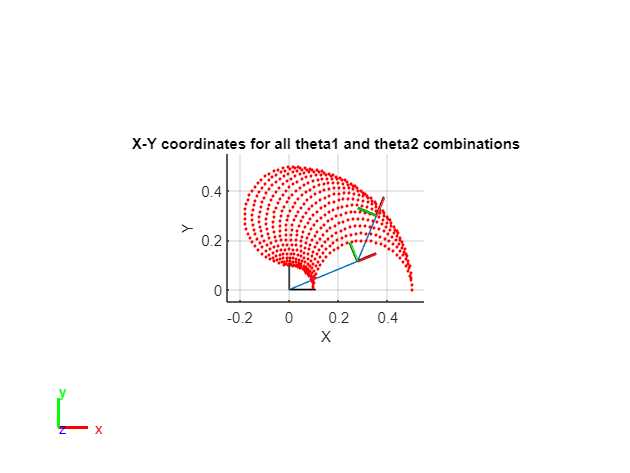

figure
show(robot);
hold all;
view (2)
ax = gca;
ax.Projection = 'orthographic';
plot(X(:),Y(:),'r.');
axis equal;
xlabel('X','fontsize',10)
ylabel('Y','fontsize',10)
title('X-Y coordinates for all theta1 and theta2 combinations','fontsize',10)
axis ([-0.25 0.55 -0.05 0.55])

## Espacio de trabajo del robot IRB120

Importamos el robot IRB120:

clear;
close all;

IRB120 = loadrobot('abbIrb120', "DataFormat", "Column");
showdetails(IRB120)

--------------------
Robot: (8 bodies)

 Idx     Body Name            Joint Name            Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------            ----------            ----------     ----------------   ----------------
   1          base        base_link-base                 fixed         base_link(0)   
   2        link_1               joint_1              revolute         base_link(0)   link_2(3)  
   3        link_2               joint_2              revolute            link_1(2)   link_3(4)  
   4        link_3               joint_3              revolute            link_2(3)   link_4(5)  
   5        link_4               joint_4              revolute            link_3(4)   link_5(6)  
   6        link_5               joint_5              revolute            link_4(5)   link_6(7)  
   7        link_6               joint_6              revolute            link_5(6)   tool0(8)  
   8         tool0          joint6-tool0                 fixed            link_6

endeffector = 'tool0'

endeffector = 'tool0'

o definomos sus parámetros dH

%           a       alpha   d     theta
dhparams = [0   	pi/2	0.29   	0;
            0.27	0       0       pi/2
            0.07	-pi/2	0	    0;
            0   	pi/2	0.302	0;
            0       -pi/2	0   	0;
            0       0       0.072    -pi];

Cálculo de algunas combinaciones articulares. Se recomiendo no calcular todas las combinaciones ya que al contar con 6 gdl el calcúlo computacional es muy pesado

N=10000;

q1=IRB120.Bodies{2}.Joint.PositionLimits(1)+ (IRB120.Bodies{2}.Joint.PositionLimits(2)-IRB120.Bodies{2}.Joint.PositionLimits(1))*rand(N,1); 
%q1 = zeros (N);   %Podemos probar q1 = 0
q2=IRB120.Bodies{3}.Joint.PositionLimits(1)+ (IRB120.Bodies{3}.Joint.PositionLimits(2)-IRB120.Bodies{3}.Joint.PositionLimits(1))*rand(N,1); 
q3=IRB120.Bodies{4}.Joint.PositionLimits(1)+ (IRB120.Bodies{4}.Joint.PositionLimits(2)-IRB120.Bodies{4}.Joint.PositionLimits(1))*rand(N,1); 
q4=IRB120.Bodies{5}.Joint.PositionLimits(1)+ (IRB120.Bodies{5}.Joint.PositionLimits(2)-IRB120.Bodies{5}.Joint.PositionLimits(1))*rand(N,1); 
q5=IRB120.Bodies{6}.Joint.PositionLimits(1)+ (IRB120.Bodies{6}.Joint.PositionLimits(2)-IRB120.Bodies{6}.Joint.PositionLimits(1))*rand(N,1); 
% No es necesario el calculo de q6 ya que al ser una articulación de tipo
% muñeca no afecta al espacio de trabajo
q6=IRB120.Bodies{7}.Joint.PositionLimits(1)+ (IRB120.Bodies{7}.Joint.PositionLimits(2)-IRB120.Bodies{7}.Joint.PositionLimits(1))*rand(N,1); 

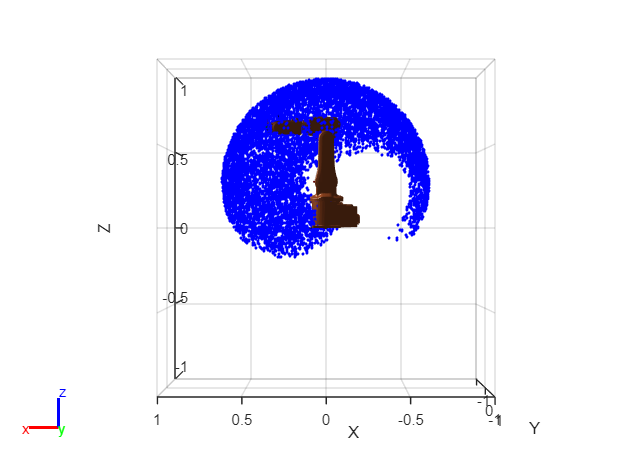

% Matriz para guardar los resultados
PPLOT=zeros(N,3);

for i=1:N

    %Calculo X, Y, Z. Opción 2:  Mediante la multiplicacion de las matrices de transformación homogéneas: 
%   A1 = makehgtform('zrotate',  q1(i)) * makehgtform('translate',[ 0 0  dhparams(1,3)]) * makehgtform('translate',[ dhparams(1,1) 0  0])* makehgtform('xrotate',  dhparams(1,2));
%   A2 = makehgtform('zrotate',  q2(i)) * makehgtform('translate',[ 0 0  dhparams(2,3)]) * makehgtform('translate',[ dhparams(2,1) 0  0])* makehgtform('xrotate',  dhparams(2,2));

%   A3 = makehgtform('zrotate',  q3(i)) * makehgtform('translate',[ 0 0  dhparams(3,3)]) * makehgtform('translate',[ dhparams(3,1) 0  0])* makehgtform('xrotate',  dhparams(3,2));
%   A4 = makehgtform('zrotate',  q4(i)) * makehgtform('translate',[ 0 0  dhparams(4,3)]) * makehgtform('translate',[ dhparams(4,1) 0  0])* makehgtform('xrotate' , dhparams(4,2));
%   A5 = makehgtform('zrotate',  q5(i)) * makehgtform('translate',[ 0 0  dhparams(5,3)]) * makehgtform('translate',[ dhparams(5,1) 0  0])*makehgtform('xrotate' , dhparams(5,2));
%   A6 = makehgtform('zrotate',  q6(i)) * makehgtform('translate',[ 0 0  dhparams(6,3)]) * makehgtform('translate',[ dhparams(6,1) 0  0])* makehgtform('xrotate' , dhparams(6,2));
%   AT = A1*A2*A3*A4*A5*A6; 
  

   %Calculo X, Y, Z. Opción 3:  MMediante la función getTransform 
  AT = getTransform(IRB120, [q1(i); q2(i); q3(i); q4(i); q5(i); q6(i)], endeffector);
  PPLOT (i, :)= AT(1:3,4);

  % Guardar resultados en la matriz PPLOT o en tres vectores X, Y, Z
  % (equivalente)
  %   X(i)=AT(1,4);
  %   Y(i)=AT(2,4);
  %   Z(i)=AT(3,4);

  

end

%Graficamos el robot y la nube de puntos del workspace
figure
show (IRB120, [0 0 0 0 0 0]');
hold on
plot3(reshape(PPLOT(:,1), [],1),reshape(PPLOT(:,2), [],1),reshape(PPLOT(:,3), [],1),'.b')
% Equivalente
%plot3 (X(:),Y(:),Z(:),'.b')
view([0,1,0])  %X-Z plane